# Neural Network for Battery SOC


$$\mathrm{SOC}=\hat{f} \left(V,I,T\right)$$


## Data

clear
load SOC_NNdata.mat trainX trainY valX valY testX testY
whos trainX trainY valX valY testX testY

  Name             Size               Bytes  Class     Attributes

  testX        39293x5              1571720  double              
  testY        39293x1               314344  double              
  trainX      669956x5             26798240  double              
  trainY      669956x1              5359648  double              
  valX         39293x5              1571720  double              
  valY         39293x1               314344  double              



## NN Architecture

numFeatures = 5;       % Number of inputs features (V, I, Temp, V_avg, I_avg)
numResponses = 1;      % Number of outputs (SOC)

numHiddenUnits = 64;   % Number of hidden units 'N', where each hidden unit for FNN represents a Neuron.

layers = [...
    featureInputLayer(numFeatures,"Normalization","zerocenter")
    fullyConnectedLayer(numHiddenUnits)       % Hidden Layer
    reluLayer 
    fullyConnectedLayer(numResponses)         % output Layer (only SOC)
    reluLayer
    regressionLayer];                         % loss function (RMSE)
 

## Training

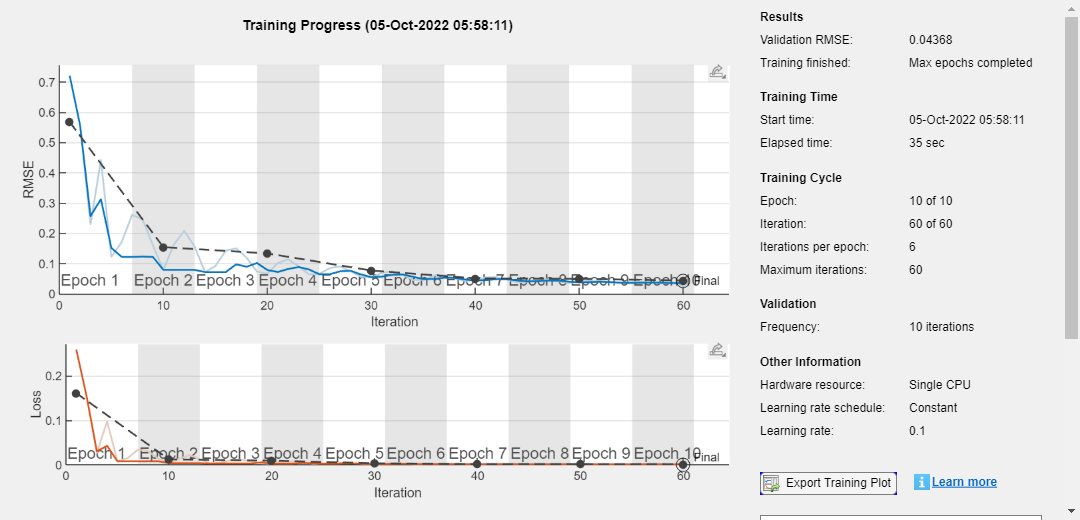

options = trainingOptions("adam", ...                    % Adam optimizer
    MaxEpochs = 10,...
    MiniBatchSize = 1e5, ...    
    InitialLearnRate = 0.1, ...
    Shuffle = "every-epoch",...
    Verbose = false,...
    ValidationFrequency = 10, ...
    ValidationData = {valX,valY},...   
    ExecutionEnvironment = "auto", ...
    Plots = "training-progress"); 

net = trainNetwork(trainX,trainY,layers,options);


save net.mat net

whos testX testY

  Name           Size              Bytes  Class     Attributes

  testX      39293x5             1571720  double              
  testY      39293x1              314344  double              



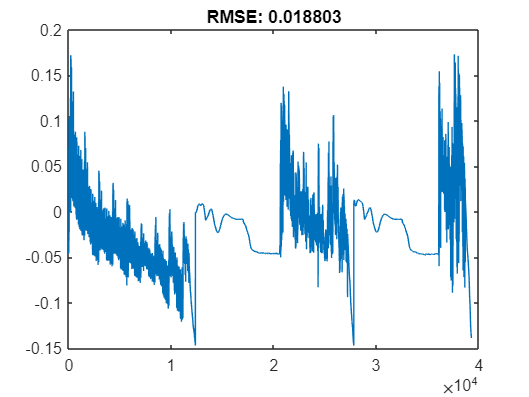


Y_Pred = predict(net,testX);
residual = testY - Y_Pred; 
RMSE = sqrt(mean(residual).^2);

figure
plot(residual); title("RMSE: "+RMSE)

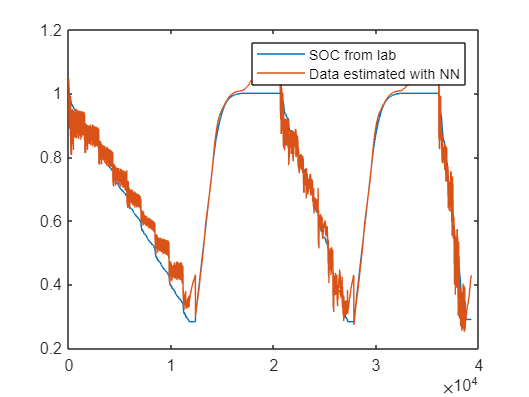


figure
plot(testY); 
hold on;
plot(Y_Pred);  
hold off
legend("SOC from lab","Data estimated with NN");